# Hackathon: Microgrid on Mars

Copyright © 2023-2024, The MathWorks, Inc.

## Introduction

You are an engineer stationed on Mars and have a rather urgent design task ahead of you. A rogue meteor has rendered the original solar array inoperative - the microgrid system now has only battery power and time is running short. You must design a new microgrid system that will provide uninterrupted power over a seven sol period (1 sol = 24 hrs 37 minutes). The system must also keep voltage between 500V and 520V at all times, as various sensitive pieces of life-support equipment cannot tolerate voltage levels outside these bounds. You only have a few Earth hours to complete your design.

## Setting up the Project

In the 'Challenge Files' directory, double-click on the MATLAB® archived project Microgrid_on_Mars.prj. The project will be installed and you will see the following folder structure:

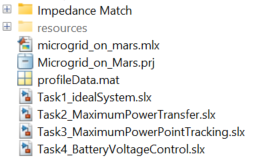

And the following data in the workspace:

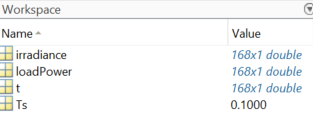

## Task 1 - Design Space Exploration

A basic system-level simulation of the microgrid system is available for exploring the design space - specifically solar power rating and battery state-of-charge (SOC). Open the model using the following command:

open_system('Task1_idealSystem')

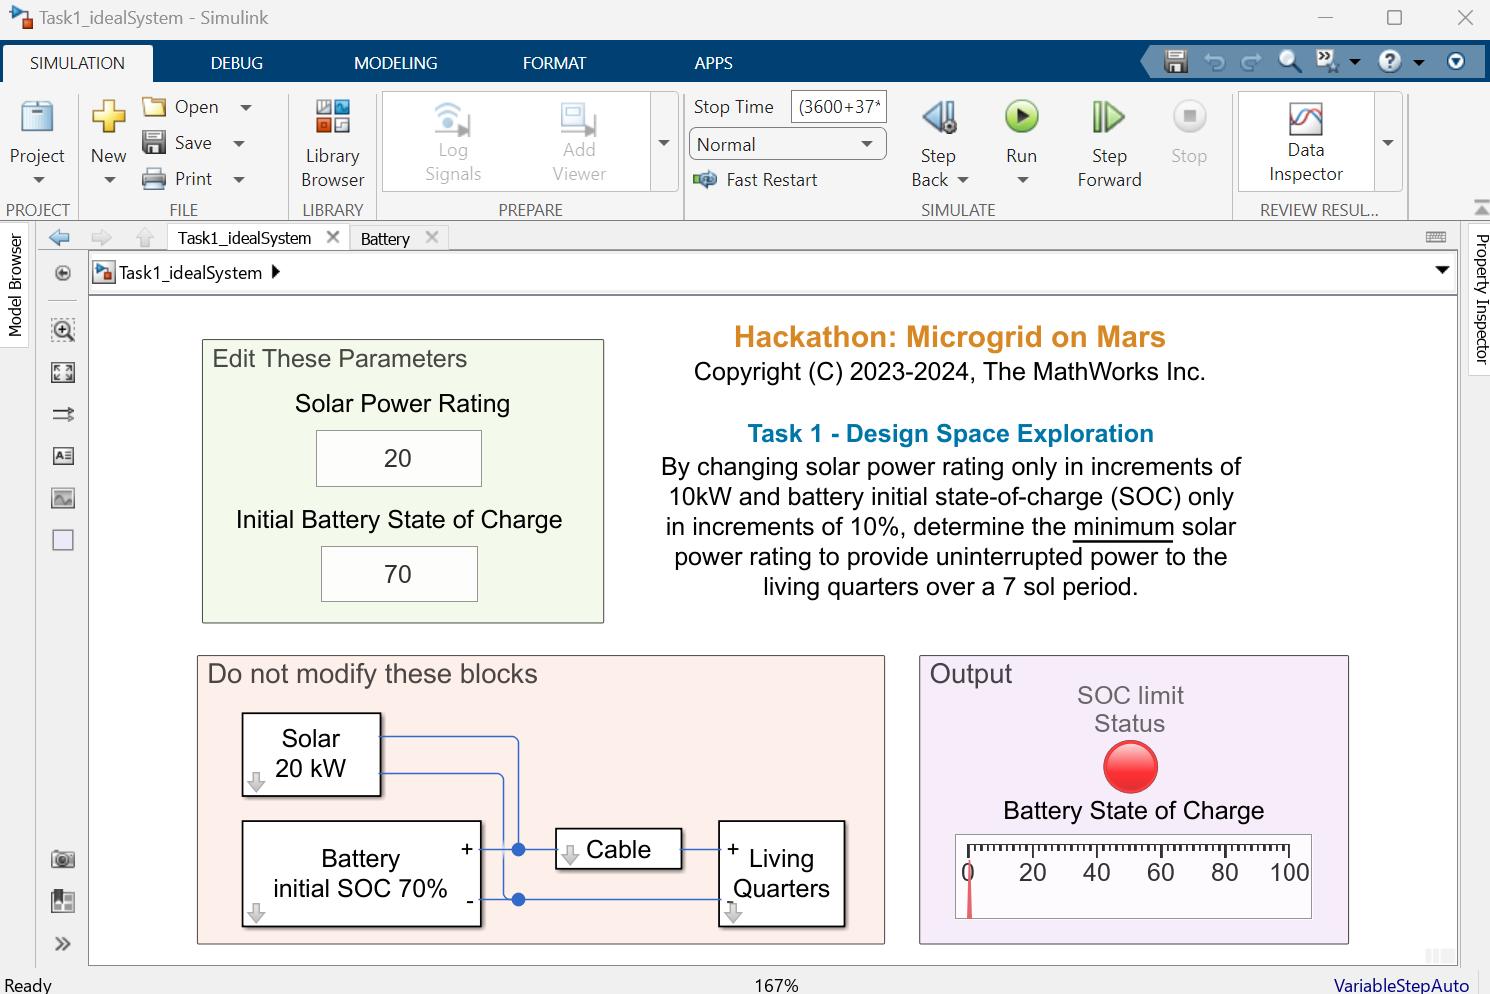

With this model, you can select solar power rating (Solar kW) and battery state of charge (SOC). To limit the design space, you should select solar power ratings in increments of 10kW and SOC in increments of 10%. To change the solar power rating and initial battery state of charge, click into the labeled edit boxes and type in the new value. 

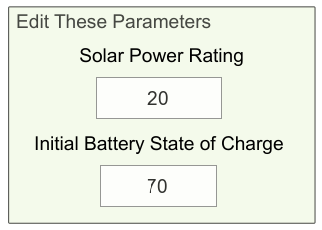

Once you have made your adjustments, press the Run button in the Simulink® Toolstrip.

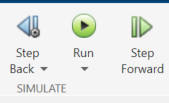

You will see that there is a lamp in the 'Output' area. This will be green when power is being delivered. You will also see an SOC gauge in this area. If the microgrid runs out of power (indicated by the battery reaching zero SOC) or the SOC exceeds 100%, the simulation will stop and the lamp will turn red. If the simulation completes with battery SOC remaining between 100% and 0%, then the lamp will remain green. As spare equipment is at a premium, the objective is to select the minimum solar power rating that will enable the living quarters to have an uninterrupted supply over the full 7 sols. Once you have a solar power rating and initial SOC, you can move to Task 2.

## Task 2 - Maximum Power Transfer

In this task, you are to determine the maximum power that a solar cell can provide by considering the principle of impedance matching. You may wish to review the examples in the Impedance Match directory to support this task.

Open the model using the following command,

open_system('Task2_MaximumPowerTransfer')

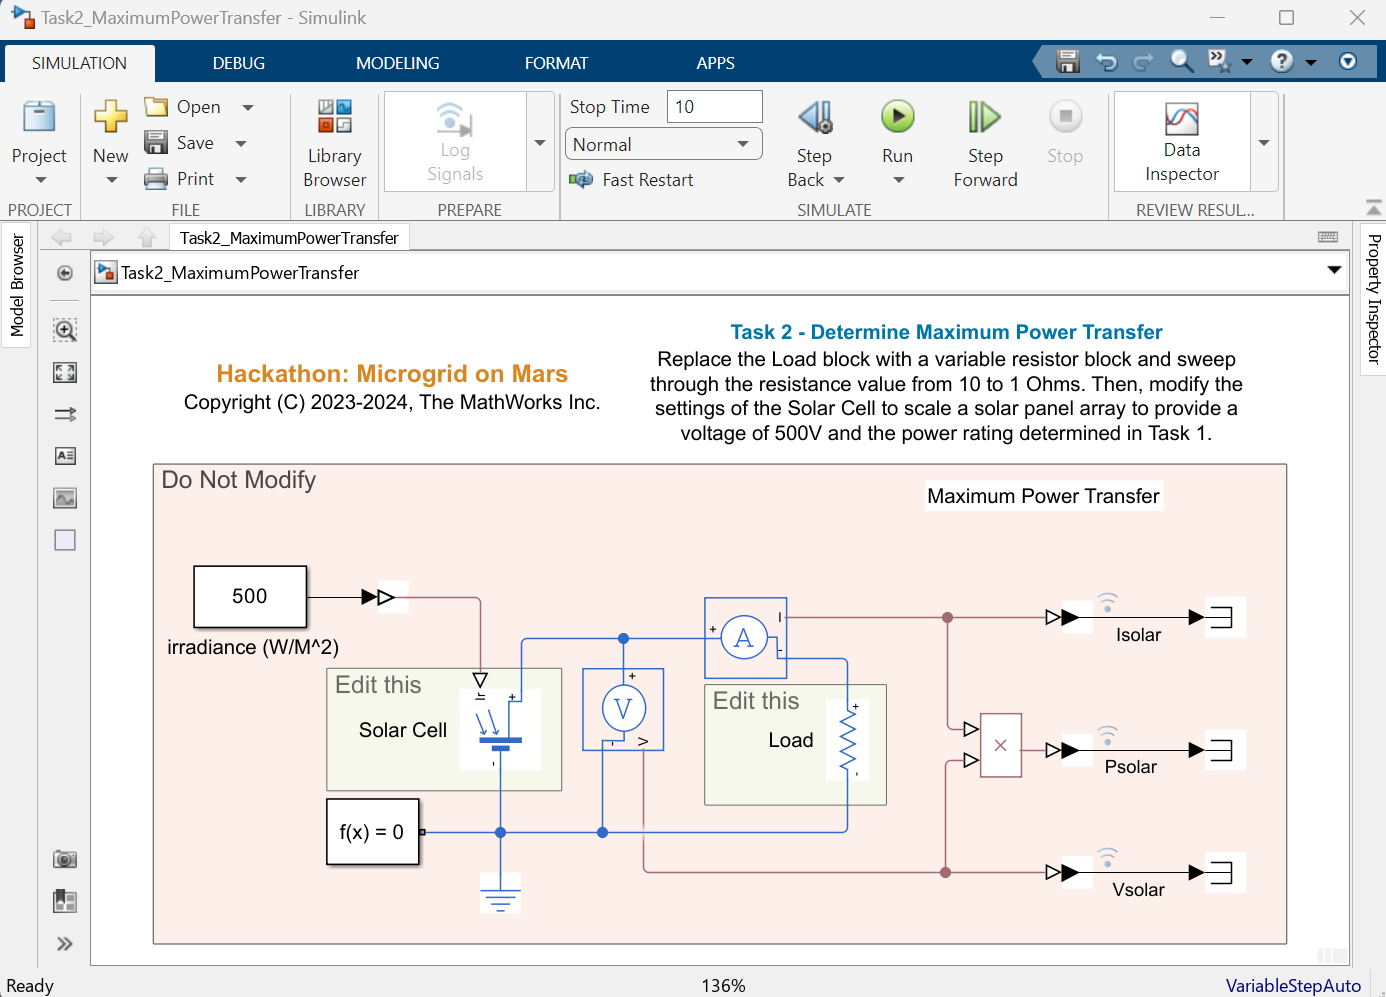

The task is to create a testing model that will show solar panel power output change as a function of load resistance. Determine the maximum power of the solar panel and then scale a solar panel array to provide a voltage of 500V and the power rating determined in Task 1.

## Task 3 - Develop Maximum Power Point Tracking (MPPT) Control

In this task, you are to tune a maximum power point tracking algorithm to control a DC-DC converter so that the maximum power of the solar array determined in Task 2 is delivered to the load. The examples in the Impedance Match directory may help you understand this task.

Open the model using the following command:

open_system('Task3_MaximumPowerPointTracking')

Copy and paste the solar array you developed in Task 2 into this model. The default settings on the MPPT algorithm are not correct and must be modified.

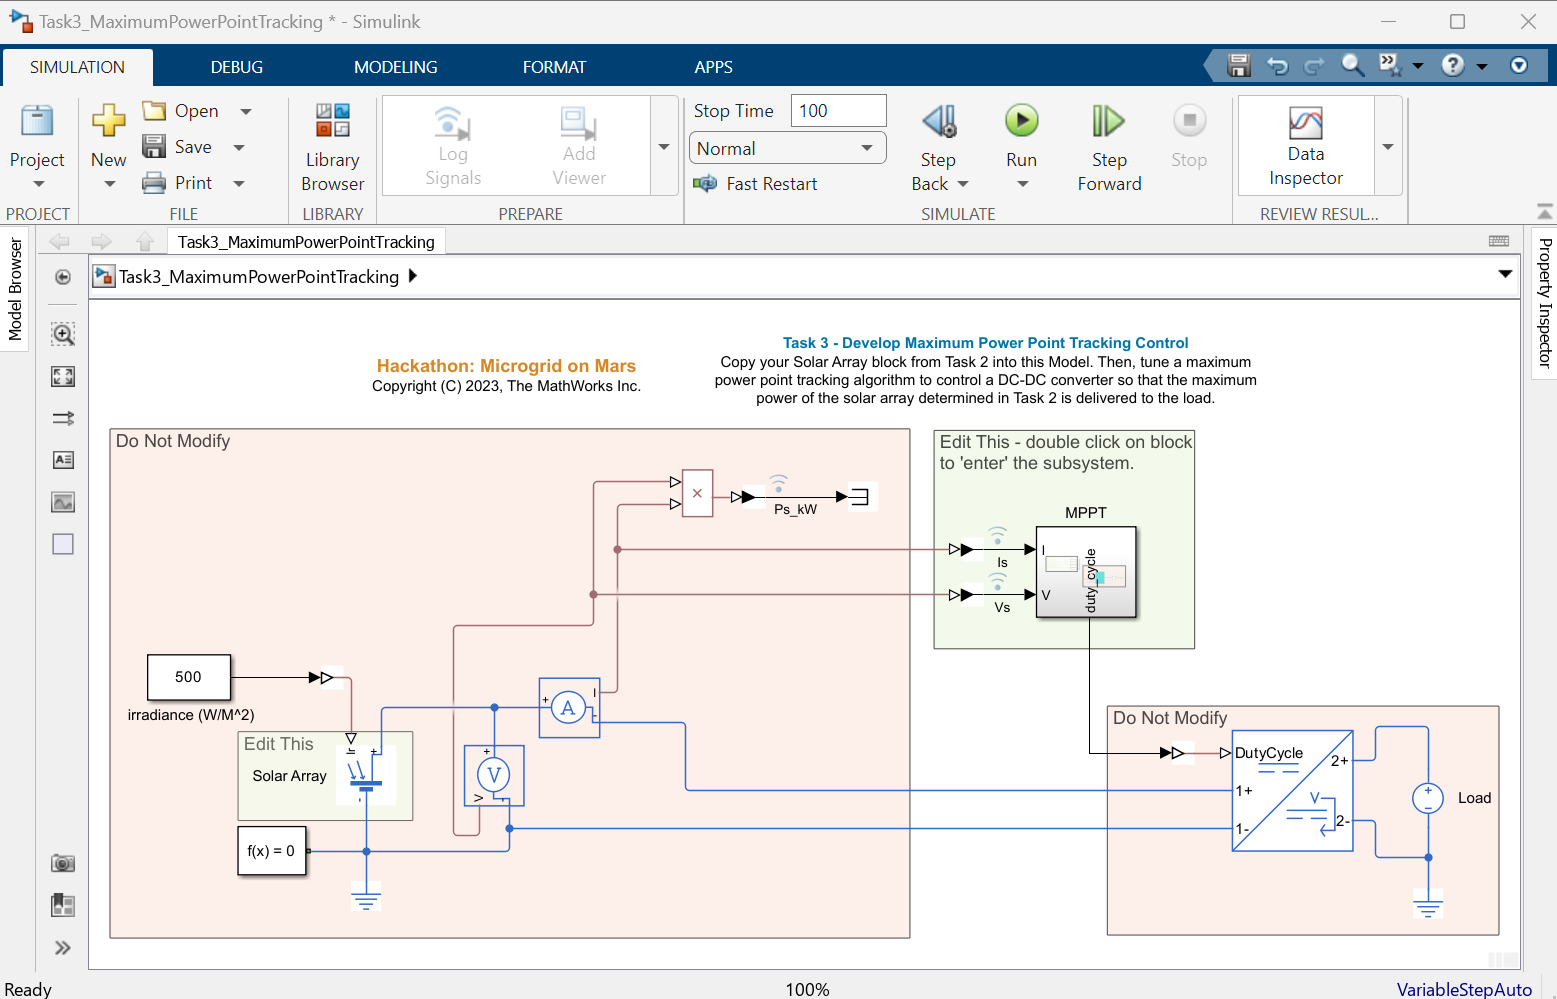

## Task 4 - Battery Voltage Control 

In this task, you are to tune a voltage control system to maintain a voltage of between 500V and 520V at the load.

Open the model using the following command:

open_system('Task4_BatteryVoltageControl')

Run the model and observe that the current control system does not meet specification - the current voltage is only 400. Adjust the Voltage Set Point and Discrete-Time Integrator block properties so that it does.

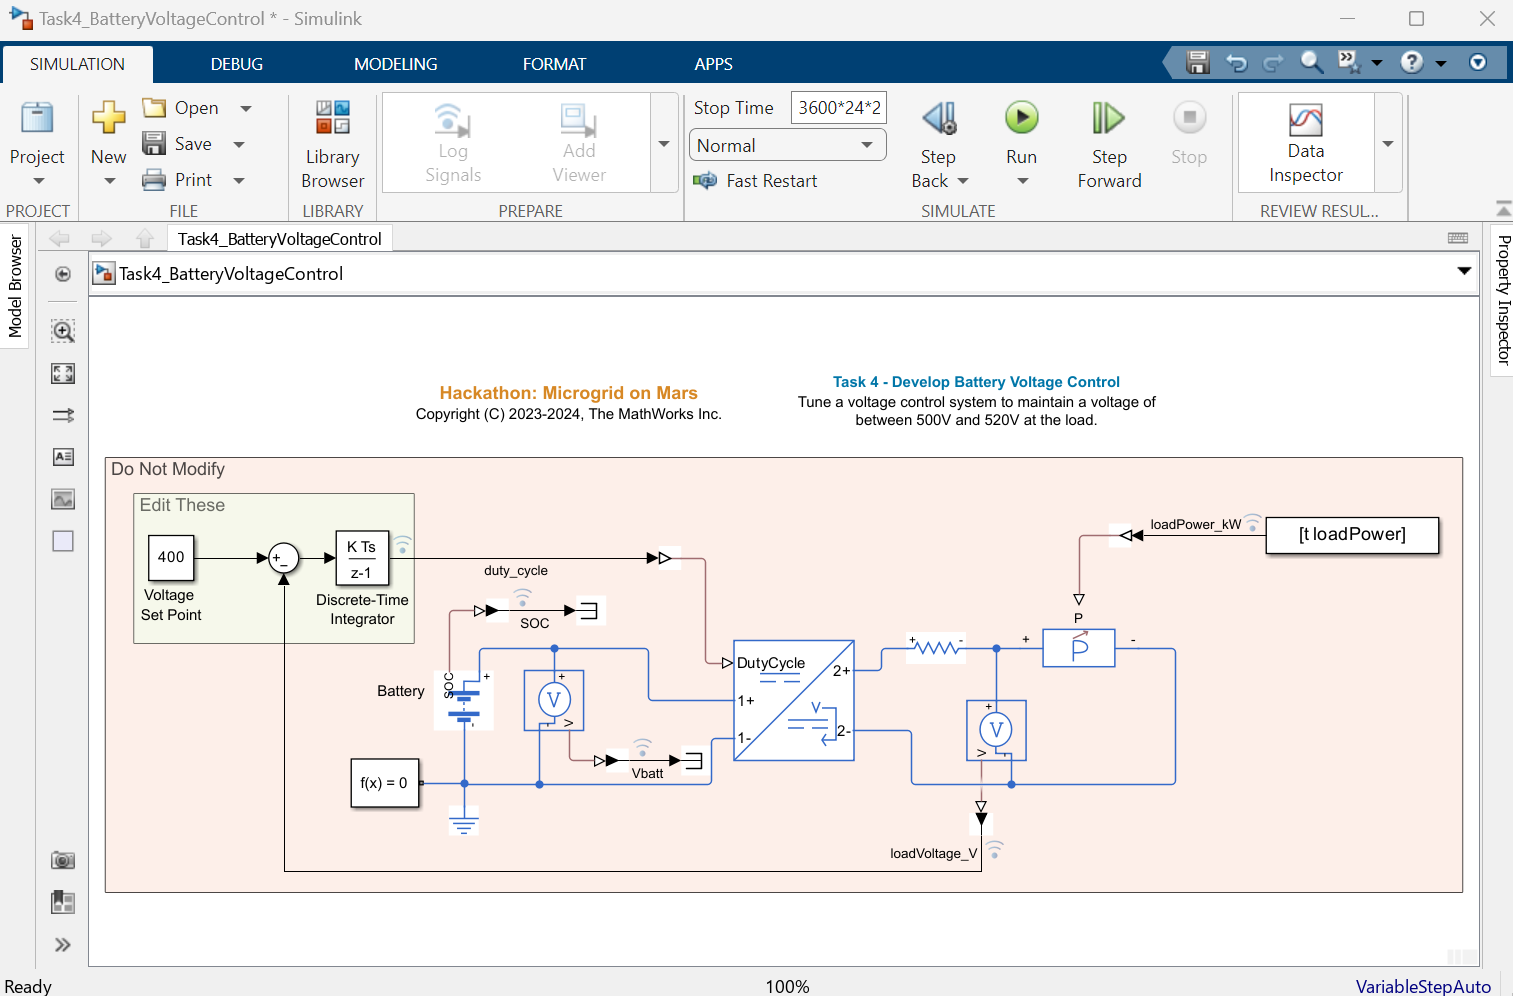

## Task 5 - Integrate and Test the Full System

Now it's time to put the system together. Combine the solar array with MPPT developed in Task 3 with the battery and voltage control developed in Task 4 and connect to the living quarters. If your design is able to provide uninterrupted supply to the living quarters for 7 sols and keep voltage between 500V and 520V, then you have accomplished your mission.

open_system('Task5_FullSystem')